# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 17-Mar-2026 10:46:28

## Create dlnetwork

Create the dlnetwork variable to contain the network layers.

net = dlnetwork;

## Add Layer Branches

Add branches to the dlnetwork. Each branch is a linear array of layers.

tempNet = [
    featureInputLayer(4,"Name","x_k")
    fullyConnectedLayer(12,"Name","hidden")
    sigmoidLayer("Name","sigmoid")
    fullyConnectedLayer(4,"Name","sortie")];
net = addLayers(net,tempNet);

tempNet = [
    featureInputLayer(2,"Name","u_k")
    fullyConnectedLayer(4,"Name","B")];
net = addLayers(net,tempNet);

tempNet = additionLayer(2,"Name","addition");
net = addLayers(net,tempNet);

% clean up helper variable
clear tempNet;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

net = connectLayers(net,"sortie","addition/in1");
net = connectLayers(net,"B","addition/in2");
net = initialize(net);

## Plot Layers

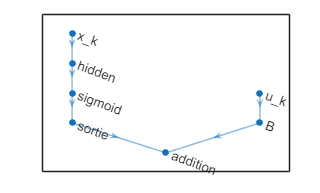

plot(net);